# FISE_MTF

Visualization of the MTF.

Create a scene sweep frequency. The frequency increases from left to right.  The contrast is 1 across all the rows (y-dimension).

Pass the scene through the default optics. Notice that the contrast amplitude decreases as frequency increases. 

The ratio of the scene amplitude (1) to the optical image amplitude is the frequency dependent scale factor $s_f$. A good approximation to the MTF is the envelope of the sweep frequency response.  This is plotted as the red curve.

Finally, notice that we did nothing to account for the edges.  So the contrast at the left and right edge is not really any good.  How we account for edges in finite cases like this is an endless annoyance.  Welcome to the club!

## **Initialize ISETCam**

ieInit;
figsave = true;
imgdir = fullfile(fiseRootPath,'chapters','images','optics','11-transform');

## Create the scene

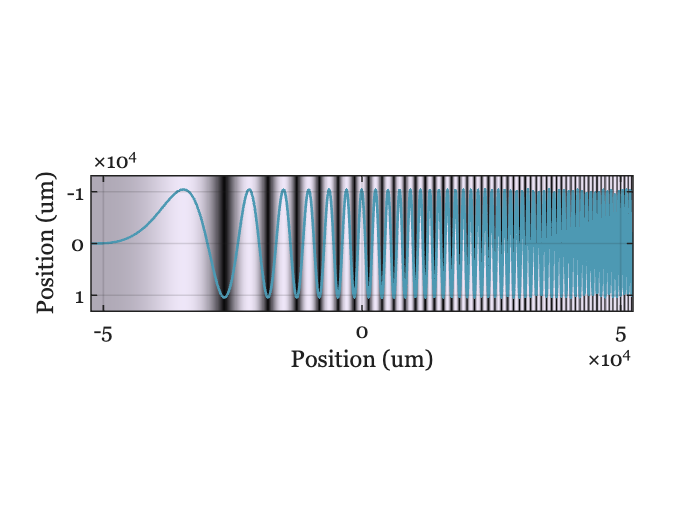

imSize = [256, 1024]; % row,col
maxF = 50;            % cycles/image
% wave = 550;           % nm
yContrast = ones(1,imSize(1));  % Constant contrast across the rows

scene = sceneCreate('sweep frequency',imSize,maxF,[],yContrast);

scene = sceneSet(scene,'fov',5);   % 50 cycles per 5 deg, so 10 cyc/deg

[g, fighdl] = plotScene(scene,'luminance hline rgb',[1,round(imSize(1) / 2)]);
ax1 = fighdl.Children;
ax1.Children(1).Color = [0.3 0.6 0.7];
if figsave, exportgraphics(gca,'scenesweep.png'); end

## Create the Optical Image

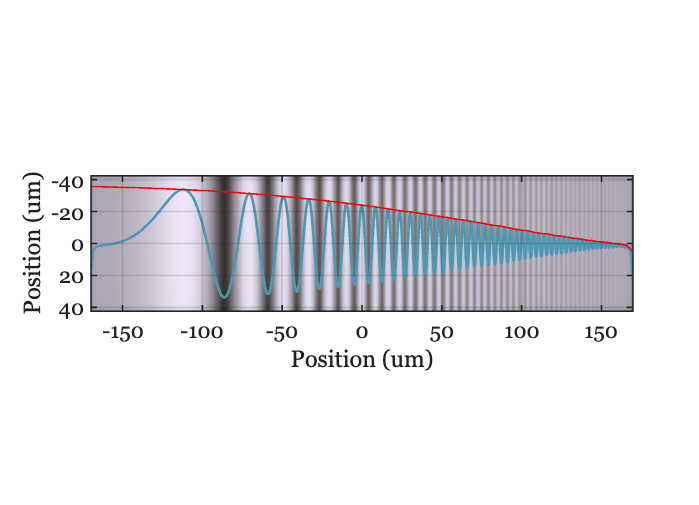

oi = oiCreate("default");

oi = oiCompute(oi,scene,'crop',true);
% fprintf('F/#: %.2f\nFocal length: %.2f\n', oiGet(oi,'fnumber'),oiGet(oi,'focal length','mm'));
[udata, fighdl] = plotOI(oi,'illuminance hline rgb',[1,round(imSize(1) / 2)]);
ax2 = fighdl.Children;
ax2.Children(1).Color = [0.3 0.6 0.7];

[upperEnvelope, lowerEnvelope] = envelope(-1*udata.data,5,'peak'); 
hold on;

plot(udata.pos,-1*upperEnvelope,'r-');

if figsave, exportgraphics(gca,'oisweep.png'); end

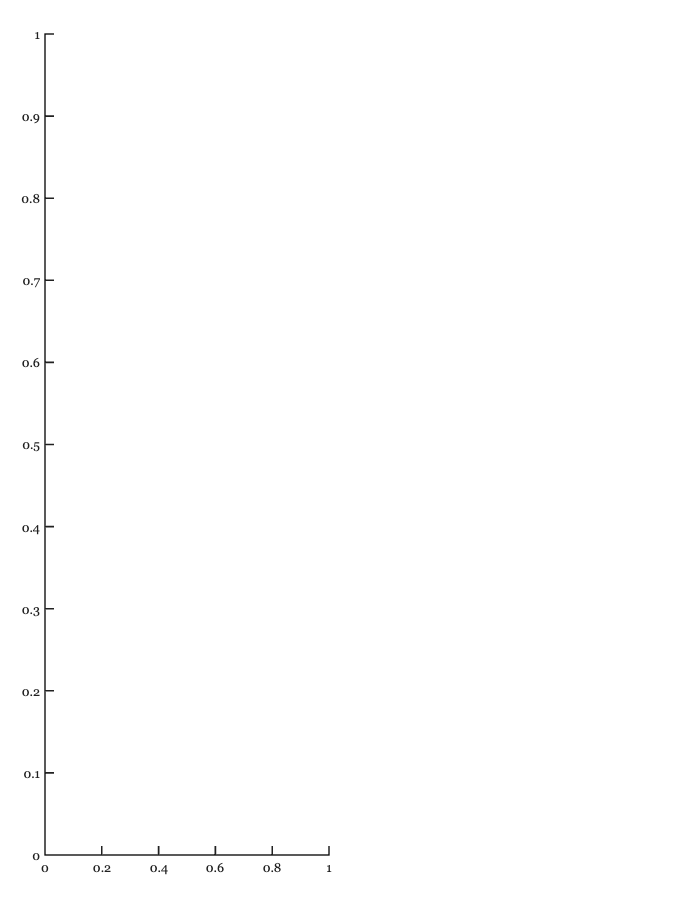

    % Create new figure with 1x2 tiles
    f = figure;
    t = tiledlayout(f,1,2,'TileSpacing','compact','Padding','compact');

    % --- Method A: copygraphics (recommended if available) ---
    axNew1 = nexttile(t,1);

    try
        copygraphics(ax1, axNew1);    % R2020a+
    catch
        % Fallback to copyobj if copygraphics not available
        copy_contents_fallback(ax1, axNew1);
    end

Unrecognized function or variable 'copy_contents_fallback'.


    axNew2 = nexttile(t,2);
    try
        copygraphics(ax2, axNew2);
    catch
        copy_contents_fallback(ax2, axNew2);
    end

    drawnow;

